# Sampling and Aliasing

## Sampling and Reconstruction at the Nyquist Frequency

Consider the analog signal $x_a(t) = \cos(20\,\pi\,t + \theta)$for $0 \le t \le 1$. It is sampled at $T_s = 0.05 $second intervals to obtain x[n]. Let $\theta = 0, \, \pi/6, \, \pi/4, \, \pi/2.$For each value of the $\theta$ values, perform the following.

- Plot $x_a(t)$ and superimpose x[n] on top of it using the plot(n,x,'o') function.

- Reconstruct the analog signal  from the samples x[n] using the sinc interpolation. Use $\Delta\,t = 0.001$, and superimpiose x[n] on it.

- You should observe that the resultant reconstruction in each case has the correct frequency but a different amplitude. Explain this observation. Comment on the role of the phase of $x_a(t)$on the sampling and reconstruction of signals.

Put your work here:

Put your explanations here:

## Aliasing with Images

We explore aliasing with sounds in Python. Here we explore aliasing with images.

Show an excellent image for the study of aliasing.

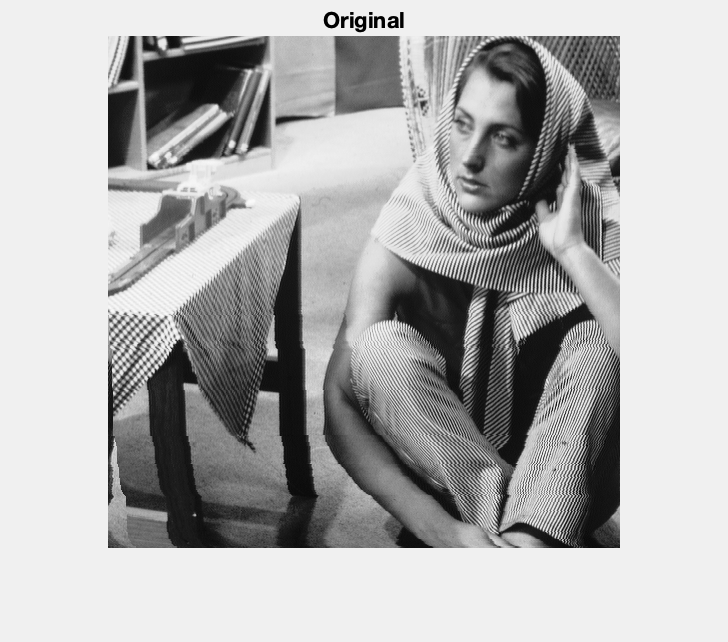

clc
clear all
close all

Im1 = imread('barbara_gray.bmp');

figure
set(gcf,'Visible','On')
imshow(Im1)
title('Original')

[height, width, depth] = size(Im1) ;

Downsample the image with no prefiltering

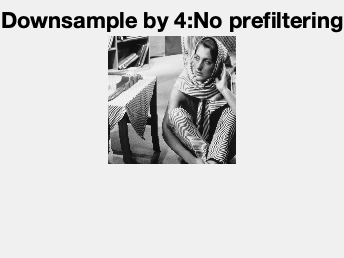

% in case bit depth is three (if trying other images)
Im2 = Im1(:,:,1) ;

% downsample no prefiltering
M = 4 ;
% write code to downsample the image by a factor of M
Im3 = Im2(1:M:end, 1:M:end);
% Im3 = imresize(Im2, [height/M,width/M],'bicubic');
% Im3=downsample(Im1,M);

% plot downsampled image
figure;
set(gcf,'Visible','On');
imshow(Im3);
title(['Downsample by ' num2str(M) ':No prefiltering']) ;

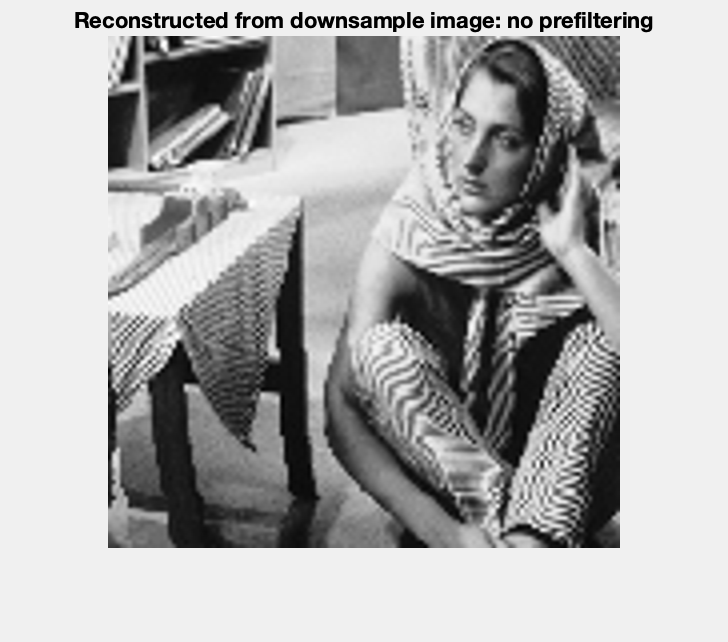


% reconstruct to original size
Im4 = imresize(Im3, [height,width],'bicubic');
figure;
set(gcf,'Visible','On');
imshow(Im4);
title(['Reconstructed from downsample image: no prefiltering'])

Downsample with low-pass prefiltering

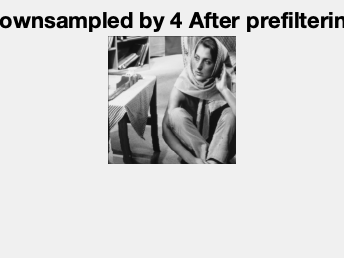

% downsample by a factor of M, after prefiltering
% apply a Gaussian filter to the image
% use the fspecial function to create a Gaussian filter
% explore reasonable values for the filter parameters
% use imfilter to apply the filter to the original image.
% put your code here

%prefiltering

SIGMA = 1.5;
HSIZE=[6*SIGMA-1,6*SIGMA-1];
filter=fspecial('Gaussian', HSIZE, SIGMA);
Im5 = imfilter(Im1,filter);
% downsample
Im6 = Im5(1:M:end, 1:M:end);
% Im6 = imresize(Im5, [height/M,width/M],'bicubic');
% Im6=downsample(Im5,M);

% plot the downsampled image with prefiltering
figure;
set(gcf,'Visible','On');
imshow(Im6);
title(['Downsampled by ' num2str(M) ' After prefiltering']) ;

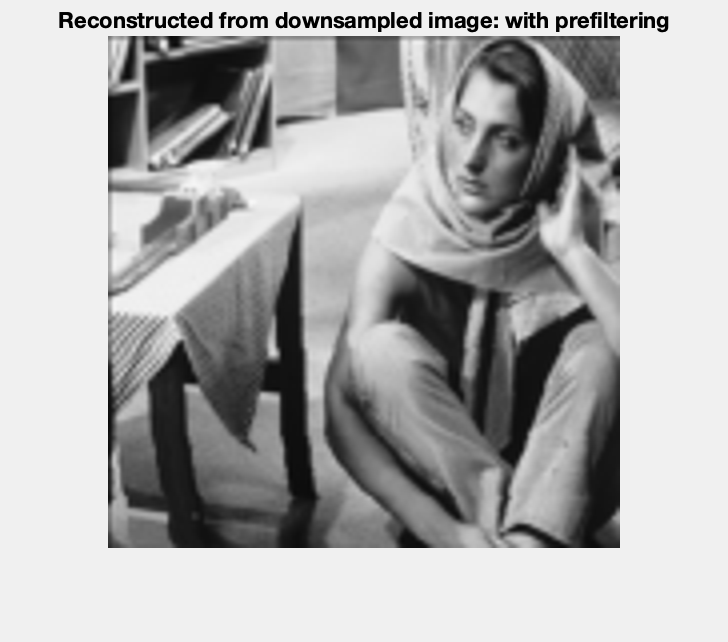


Im7 = imresize(Im6,[height,width],'bicubic') ;
figure;
set(gcf,'Visible','On');
imshow(Im7);
title('Reconstructed from downsampled image: with prefiltering')

## Explain your Observations

Explain why aliasing should occur. Explain what you observe with aliasing. Explain why there is an improvement with the application of a prefilter.

Aliasing is when consecutive signals partially overlap each other. It refers to the distortions and artifacts that result when the signal reconstructued from samples is different from the original signal, in this case = an image. This effect can be seen in the reconstructued image without prefiltering, where the edges are harsher and there are jagged artifacts in the woman's pants and scarf.  

Prefilter: The Gaussian filter is a linear filter. It blur the image and usually used to reduce Gaussian noise (high frequency components). Reduce the sharpness of the edges and has the effect of blurring the images. This reduces the effect of aliasing but increases blur of the image. When choosing the parameters for the Gaussian filter, the larger the sigma, the more blur is introduced, but less aliasing in the image. 